# Basically rewrite the pchavedemo written by FJS due to some incompatibility

rng default

% case 1, pchavedemo('demo1'): PCHAVE vs. Matlab's PWELCH, both with Hamming window
Fs=1000; t=0:1/Fs:0.296;
lwin=64; olap=50; nfft=256;
X{1} = cos(2*pi*t*200)+randn(size(t)); % A cosine of 200Hz plus noise
% the order of output matters, if you only need specific output, you still need
% the others before that, but can ommit the rest; so does the input
[SD,jk1,jk2,jk3,jk4,jk5,Snon]=pchave(X,lwin,olap,nfft,Fs,'MAD','hamming');

Window size for spectral density:      0.1
Number of overlapping data segments: 8
Number of  segments is not  integer: 9 / 297 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 244 / 256 frequencies
Iteration 003 mandated by 143 / 256 frequencies
Iteration 004 mandated by 072 / 256 frequencies
Iteration 005 mandated by 028 / 256 frequencies
Iteration 006 mandated by 004 / 256 frequencies
Error bounds reflect confidence level of  95.0%


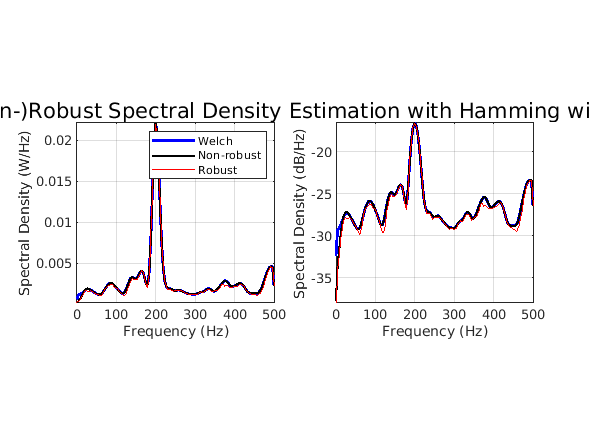

[Swelch,F]=pwelch(X{1},lwin,ceil(olap*lwin/100),nfft,Fs,'onesided');
figure
ah(1)=subplot(121);
plin(1)=plot(F,Swelch,'b-','LineW',2); hold on
plin(2)=plot(F,Snon,'k-','LineW',1.5);
plin(3)=plot(F,SD,'r-','LineW',1); axis tight; grid on
xl(1)=xlabel('Frequency (Hz)'); yl(1)=ylabel('Spectral Density (W/Hz)');
ah(2)=subplot(122);
plog(1)=plot(F,10*log10(Swelch),'b-','LineW',2); hold on
plog(2)=plot(F,10*log10(Snon),'k-','LineW',1.5);
plog(3)=plot(F,10*log10(SD),'r-','LineW',1);
axis tight; grid on; fig2print(gcf,'landscape')
xl(2)=xlabel('Frequency (Hz)'); yl(2)=ylabel('Spectral Density (dB/Hz)');
shrink(ah,1,2); axes(ah(1)); l=legend('Welch','Non-robust','Robust');
st=supertit(ah,...
    ['(Non-)Robust Spectral Density Estimation with Hamming window']);
movev(st,.1);


% case 2, pchavedemo('demo2'): PCHAVE's robust estimate; Hamming vs. dpss window
rng default
Fs=1000; t=0:1/Fs:0.296;
lwin=64; olap=70; nfft=256;
X{1} = cos(2*pi*t*200)+randn(size(t)); % A cosine of 200Hz plus noise
[SDH,F]=pchave(X,lwin,olap,nfft,Fs,'MAD','hamming');

Window size for spectral density:      0.1
Number of overlapping data segments: 12
Number of  segments is not  integer: 13 / 297 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 246 / 256 frequencies
Iteration 003 mandated by 134 / 256 frequencies
Iteration 004 mandated by 076 / 256 frequencies
Iteration 005 mandated by 012 / 256 frequencies
Error bounds reflect confidence level of  95.0%


[SDD]=pchave(X,lwin,olap,nfft,Fs,'MAD','dpss');

Window size for spectral density:      0.1
Number of overlapping data segments: 12
Number of  segments is not  integer: 13 / 297 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 240 / 256 frequencies
Iteration 003 mandated by 146 / 256 frequencies
Iteration 004 mandated by 063 / 256 frequencies
Iteration 005 mandated by 015 / 256 frequencies
Iteration 006 mandated by 001 / 256 frequencies
Error bounds reflect confidence level of  95.0%


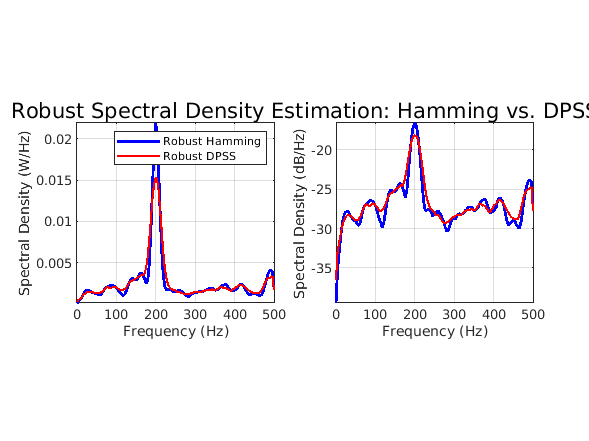

figure
ah(1)=subplot(121);
plin(1)=plot(F,SDH,'b-','LineW',2); hold on
plin(2)=plot(F,SDD,'r-','LineW',1.5); axis tight; grid on
xl(1)=xlabel('Frequency (Hz)'); yl(1)=ylabel('Spectral Density (W/Hz)');
ah(2)=subplot(122);
plog(1)=plot(F,10*log10(SDH),'b-','LineW',2); hold on
plog(2)=plot(F,10*log10(SDD),'r-','LineW',1.5);
axis tight; grid on; fig2print(gcf,'landscape')
xl(2)=xlabel('Frequency (Hz)'); yl(2)=ylabel('Spectral Density (dB/Hz)');
shrink(ah,1,2); axes(ah(1)); l=legend('Robust Hamming','Robust DPSS');
st=supertit(ah,...
    ['Robust Spectral Density Estimation: Hamming vs. DPSS']);
movev(st,.1);


% case 3, pchavedemo('demo3'): PCHAVE's robust vs. nonrobust estimate with dpss window
rng default
Fs=1000; t=0:1/Fs:0.296;
lwin=64; olap=70; nfft=256;
X{1} = cos(2*pi*t*200)+randn(size(t)); % A cosine of 200Hz plus noise
[SDD,F,jk1,jk2,jk3,jk4,SnonD]=pchave(X,lwin,olap,nfft,Fs,'MAD','dpss');

Window size for spectral density:      0.1
Number of overlapping data segments: 12
Number of  segments is not  integer: 13 / 297 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 240 / 256 frequencies
Iteration 003 mandated by 146 / 256 frequencies
Iteration 004 mandated by 063 / 256 frequencies
Iteration 005 mandated by 015 / 256 frequencies
Iteration 006 mandated by 001 / 256 frequencies
Error bounds reflect confidence level of  95.0%


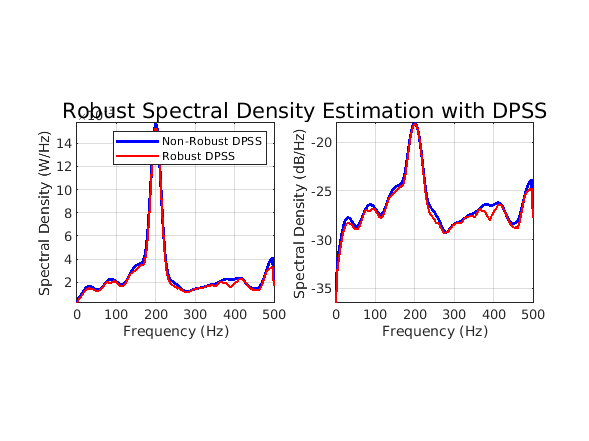

figure
ah(1)=subplot(121);
plin(1)=plot(F,SnonD,'b-','LineW',2); hold on
plin(2)=plot(F,SDD,'r-','LineW',1.5); axis tight; grid on
xl(1)=xlabel('Frequency (Hz)'); yl(1)=ylabel('Spectral Density (W/Hz)');
ah(2)=subplot(122);
plog(1)=plot(F,10*log10(SnonD),'b-','LineW',2); hold on
plog(2)=plot(F,10*log10(SDD),'r-','LineW',1.5);
axis tight; grid on; fig2print(gcf,'landscape')
xl(2)=xlabel('Frequency (Hz)'); yl(2)=ylabel('Spectral Density (dB/Hz)');
shrink(ah,1,2); axes(ah(1)); l=legend('Non-Robust DPSS','Robust DPSS');
st=supertit(ah,['Robust Spectral Density Estimation with DPSS']);
movev(st,.1)


% case 4, pchavedemo('demo4'): PCHAVE's robust estimate with linear and logarithmic errors
rng default
Fs=1000; t=0:1/Fs:0.296;
lwin=64; olap=70; nfft=256;
X{1} = cos(2*pi*t*200)+randn(size(t)); % A cosine of 200Hz plus noise
[SD,F,Ulog,Llog,Ulin,Llin,Snon]=pchave(X,lwin,olap,nfft,Fs,'MAD','dpss');

Window size for spectral density:      0.1
Number of overlapping data segments: 12
Number of  segments is not  integer: 13 / 297 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 240 / 256 frequencies
Iteration 003 mandated by 146 / 256 frequencies
Iteration 004 mandated by 063 / 256 frequencies
Iteration 005 mandated by 015 / 256 frequencies
Iteration 006 mandated by 001 / 256 frequencies
Error bounds reflect confidence level of  95.0%


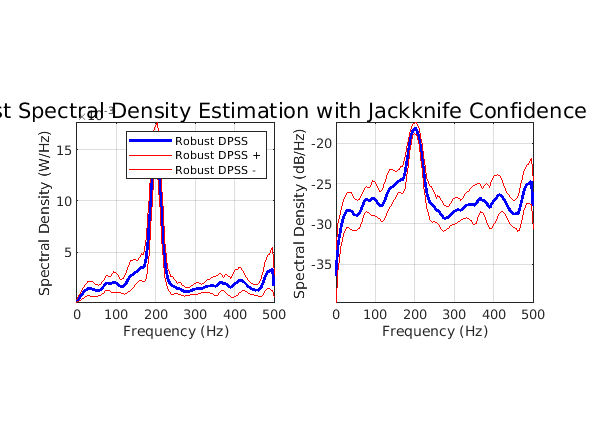

figure
ah(1)=subplot(121);
plin(1)=plot(F,SD,'b-','LineW',2); hold on
plin(2)=plot(F,Ulin,'r-','LineW',1);
plin(3)=plot(F,Llin,'r-','LineW',1); axis tight; grid on
xl(1)=xlabel('Frequency (Hz)'); yl(1)=ylabel('Spectral Density (W/Hz)');
ah(2)=subplot(122);
plog(1)=plot(F,10*log10(SD),'b-','LineW',2); hold on
plog(2)=plot(F,10*log10(Ulog),'r-','LineW',1);  % ulog and llog are used for logscale, and always appear with log()
plog(3)=plot(F,10*log10(Llog),'r-','LineW',1);
axis tight; grid on; fig2print(gcf,'landscape')
xl(2)=xlabel('Frequency (Hz)'); yl(2)=ylabel('Spectral Density (dB/Hz)');
shrink(ah,1,2); axes(ah(1)); l=legend('Robust DPSS','Robust DPSS +','Robust DPSS -');
st=supertit(ah,...
    ['Robust Spectral Density Estimation with Jackknife Confidence Bounds']);
movev(st,.1)


% case 5, pchavedemo('demo5'): PCHAVE's quantile-quantile quality control plots
rng default
Fs=1000; t=0:1/Fs:2.96;
lwin=64; olap=70; nfft=256;
X{1} = cos(2*pi*t*200)+randn(size(t)); % A cosine of 200Hz plus noise
% In statistics, the kth order statistic of a statistical sample is equal to its kth-smallest value
[SD,F,Ulog,Llog,Ulin,Llin,Snon,Qnon,Qrob,Qchi]=...
    pchave(X,lwin,olap,nfft,Fs,'MAD','dpss');

Window size for spectral density:      0.1
Number of overlapping data segments: 145
Number of  segments is not  integer: 17 / 2961 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 250 / 256 frequencies
Iteration 003 mandated by 224 / 256 frequencies
Iteration 004 mandated by 038 / 256 frequencies
Error bounds reflect confidence level of  95.0%


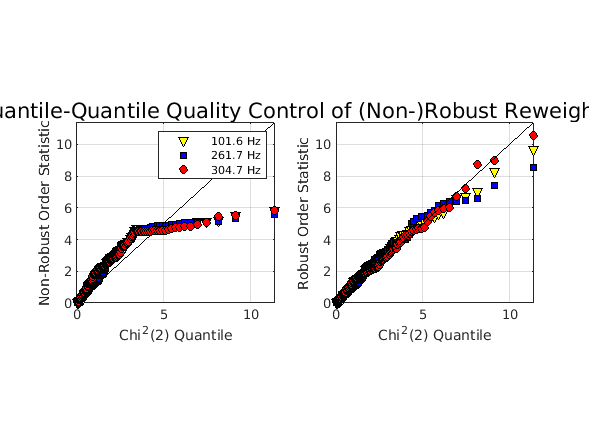

% Pick three random frequencies to test your thing on, but not
% beginning or end
rf=indeks(sort(unidrnd(length(F),1,5)),[2 3 4]);
figure
ah(1)=subplot(121);
plin(1)=plot(Qchi,Qnon(rf(1),:),'v'); hold on
plin(2)=plot(Qchi,Qnon(rf(2),:),'s');
plin(3)=plot(Qchi,Qnon(rf(3),:),'o');
pref(1)=refline(1,0);   % plot a reference line, slope and intercept, no more arguments allowed
axis tight; grid on
xl(1)=xlabel('Chi^2(2) Quantile'); yl(1)=ylabel('Non-Robust Order Statistic');
ah(2)=subplot(122);
plog(1)=plot(Qchi,Qrob(rf(1),:),'v'); hold on
plog(2)=plot(Qchi,Qrob(rf(2),:),'s');
plog(3)=plot(Qchi,Qrob(rf(3),:),'o');
pref(2)=refline(1,0);
axis tight; grid on; fig2print(gcf,'landscape')
xl(2)=xlabel('Chi^2(2) Quantile'); yl(2)=ylabel('Robust Order Statistic');
shrink(ah,1,2); axes(ah(1));
l=legend(sprintf('%6.1f Hz',F(rf(1))),sprintf('%6.1f Hz',F(rf(2))),...
	   sprintf('%6.1f Hz',F(rf(3))));
st=supertit(ah,...
    ['Quantile-Quantile Quality Control of (Non-)Robust Reweighting']);
movev(st,.1)
set([plin(1) plog(1)],'MarkerE','k','MarkerF','y')
set([plin(2) plog(2)],'MarkerE','k','MarkerF','b')
set([plin(3) plog(3)],'MarkerE','k','MarkerF','r')
set(pref,'Color','k')


% case 6, pchavedemo('demo6'): PCHAVE's spectral estimates with different confidence intervals
%%% the higher val, the larger the interval (area between)
rng default
Fs=1000; t=0:1/Fs:0.296;
lwin=64; olap=70; nfft=256;
X{1} = cos(2*pi*t*200)+randn(size(t)); % A cosine of 200Hz plus noise
[SD,F,Ulog68,Llog68,Ulin68,Llin68]=...
    pchave(X,lwin,olap,nfft,Fs,'MAD','dpss',4,68);

Window size for spectral density:      0.1
Number of overlapping data segments: 12
Number of  segments is not  integer: 13 / 297 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 240 / 256 frequencies
Iteration 003 mandated by 146 / 256 frequencies
Iteration 004 mandated by 063 / 256 frequencies
Iteration 005 mandated by 015 / 256 frequencies
Iteration 006 mandated by 001 / 256 frequencies
Error bounds reflect confidence level of  68.0%


[SD,F,Ulog95,Llog95,Ulin95,Llin95]=...
    pchave(X,lwin,olap,nfft,Fs,'MAD','dpss',4,95);

Window size for spectral density:      0.1
Number of overlapping data segments: 12
Number of  segments is not  integer: 13 / 297 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 240 / 256 frequencies
Iteration 003 mandated by 146 / 256 frequencies
Iteration 004 mandated by 063 / 256 frequencies
Iteration 005 mandated by 015 / 256 frequencies
Iteration 006 mandated by 001 / 256 frequencies
Error bounds reflect confidence level of  95.0%


[SD,F,Ulog99,Llog99,Ulin99,Llin99]=...
    pchave(X,lwin,olap,nfft,Fs,'MAD','dpss',4,99);

Window size for spectral density:      0.1
Number of overlapping data segments: 12
Number of  segments is not  integer: 13 / 297 points truncated
Iteration 001 mandated by 256 / 256 frequencies
Iteration 002 mandated by 240 / 256 frequencies
Iteration 003 mandated by 146 / 256 frequencies
Iteration 004 mandated by 063 / 256 frequencies
Iteration 005 mandated by 015 / 256 frequencies
Iteration 006 mandated by 001 / 256 frequencies
Error bounds reflect confidence level of  99.0%


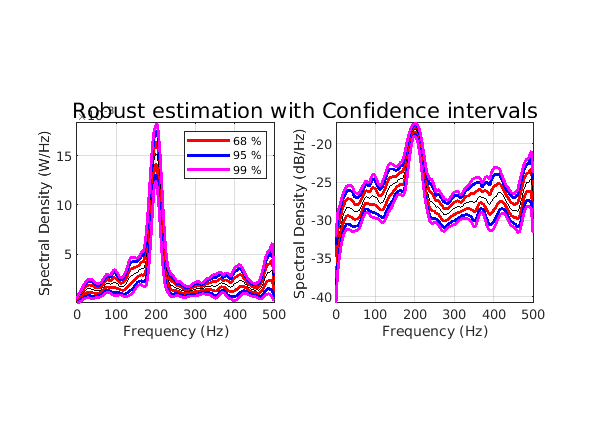

% Pick three random frequencies to test your thing on, but not
% beginning or end
figure
ah(1)=subplot(121);
plin(1)=plot(F,Ulin68,'r-','LineW',2); hold on
plin(2)=plot(F,Ulin95,'b-','LineW',2);
plin(3)=plot(F,Ulin99,'m-','LineW',2);
plin(4)=plot(F,SD,'k-','LineW',1);
plin(5)=plot(F,Llin68,'r-','LineW',2);
plin(6)=plot(F,Llin95,'b-','LineW',2);
plin(7)=plot(F,Llin99,'m-','LineW',2);
axis tight; grid on
xl(1)=xlabel('Frequency (Hz)'); yl(1)=ylabel('Spectral Density (W/Hz)');
ah(2)=subplot(122);
plog(1)=plot(F,10*log10(Ulog68),'r-','LineW',2); hold on
plog(2)=plot(F,10*log10(Ulog95),'b-','LineW',2);
plog(3)=plot(F,10*log10(Ulog99),'m-','LineW',2);
plog(4)=plot(F,10*log10(SD),'k-','LineW',1);
plog(5)=plot(F,10*log10(Llog68),'r-','LineW',2);
plog(6)=plot(F,10*log10(Llog95),'b-','LineW',2);
plog(7)=plot(F,10*log10(Llog99),'m-','LineW',2);
axis tight; grid on; fig2print(gcf,'landscape')
xl(2)=xlabel('Frequency (Hz)'); yl(2)=ylabel('Spectral Density (dB/Hz)');
shrink(ah,1,2); axes(ah(1));
l=legend('68 %','95 %','99 %');  % always specify legend after all plottings to ensure only first k items have legends
st=supertit(ah,['Robust estimation with Confidence intervals']);
movev(st,.1)